# MPC and constraint handling in control101

This livescript is a brief manual in support of the app ***mpcconstraints_lab_control101.mlapp***.   This is a simple interface to understand and investigate how the inclusion of a constraints within an MPC law affects the performance.

What is clear is that constraints change behaviour and moreover, they change optimum behaviour. By including constraints within the optimisation, MPC laws can determine optimal behavour in the presence of constraints and thus outperform alternatives using more ad-hoc approaches. This app focuses on finite horizon approaches such as GPC as in those cases, feasibility is easily guaranteed for input constraints.

- For more help on how to get the most of this app, please see the videos [here](https://www.youtube.com/playlist?list=PLs7mcKy_nInHEjth9P3m_bxd6D24IVSzz).

- For more information on the supporting files for MPC, please see the following livescripts: ***mpcsourcecode_control101.mlx.***

For more background on MPC readers can look at the website [https://sites.google.com/sheffield.ac.uk/controleducation/introtompcbook](https://sites.google.com/sheffield.ac.uk/controleducation/introtompcbook) and also a range of popular text books such as that by the author: **A first course in predictive control: 2nd Edition**,  J.A. Rossiter, CRC Press (Taylor and Francis group), 2018, ISBN 9781138099340.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Introduction

- Constraints and the constrained optimsation problem with predictions

- Investigating the impact of constraints on behaviour

- Interface and user interaction

## 1. Introduction

It is assumed that user has already gone through the materials in the following livescripts and apps which provide background on MPC and basic tuning.

- mpcsourcecode_control101.mlx

- predictionconcepts_control101_manual.mlx, predictionconcepts_control101.mlapp

- mpctuning_control101_manual.mlx, mpctuning_control101.mlapp     

- mpcfailing_control101_manual.mlx, mpcfailing_control101.mlapp

- mpctfilter_control101_manual.mlx, mpctfilter_control101.mlapp

Consequently, that material is not repeated, including notation. That material also includes some information on constraints, but we will repeat some aspects of that as it is central to this app.

## 2. Constraints and the constrained optimsation problem with predictions

### 2.1 Unconstrained optimisation

The user needs to select the future inputs which will lead to the best predicted behaviour. In order to automate the decision making and ensure better consistency, we need some quantitative measure of best. Within the MPC community it is accepted that 2-norm performance measures have a number advantages over alternatives which make them the preferred option in general (a deeper discussion of this point is not appropriate in an introductory resource). Hence  consider the following measure for future performance:


$$J=\sum_{i=1}^{\textrm{ny}} {\left(r-y\left(k+i|k\right)\right)}^2 +\lambda \sum_{i=0}^{\textrm{nu}} \Delta u{\left(k+i|k\right)}^2 ;\;\;\;\;\;\;\;\;\Delta u\left(k\right)=u\left(k\right)-u\left(k-1\right)$$
      

In simple terms the MPC control law reduces to choosing, at every sample, the set of future input increments which minimises J.

Substituting the predictions (see **mpcsourcecode_control101.mlx**)  into the performance index above gives the following.


$$E=\underset{R}{\underbrace{\left\lbrack \begin{array}{c}
r\left(k+1\right)\\
r\left(k+2\right)\\
\vdots \\
r\left(k+\textrm{ny}\right)
\end{array}\right\rbrack } } -H\underset{\Delta U_{\textrm{fut}} }{\underbrace{\left\lbrack \begin{array}{c}
\Delta u\left(k|k\right)\\
\Delta u\left(k+1|k\right)\\
\vdots \\
\Delta u\left(k+\textrm{nu}-1|k\right)
\end{array}\right\rbrack } } -P\underset{\Delta U_{\textrm{past}} }{\underbrace{\left\lbrack \begin{array}{c}
\Delta u\left(k-1\right)\\
\Delta u\left(k-2\right)\\
\vdots \\
\Delta u\left(k-m\right)
\end{array}\right\rbrack } } -Q\underset{Y_{\textrm{past}} }{\underbrace{\left\lbrack \begin{array}{c}
y\left(k\right)\\
y\left(k-1\right)\\
\vdots \\
y\left(k-m\right)
\end{array}\right\rbrack } } ;\;\;U=\left\lbrack \begin{array}{c}
\Delta u\left(k|k\right)\\
\Delta u\left(k+1|k\right)\\
\vdots \\
\Delta u\left(k+\textrm{nu}-1|k\right)
\end{array}\right\rbrack$$
     


$$J=E^T E+{\lambda U}^T U={\left(R-H\Delta U_{\textrm{fut}} -P\Delta U_{\textrm{past}} -QY_{\textrm{past}} \right)}^T \left(R-H\Delta U_{\textrm{fut}} -P\Delta U_{\textrm{past}} -QY_{\textrm{past}} \right)$$


$J={\left(\Delta U_{\textrm{fut}} \right)}^T \left(H^T H+\lambda I\right)\Delta U_{\textrm{fut}} \;+{{2\left(\Delta U_{\textrm{fut}} \right)}^T H}^T \left(R-P\Delta U_{\textrm{past}} -QY_{\textrm{past}} \right)+\;\ldotp \ldotp \ldotp$ (bits not dependent on the d.o.f. so ignored)

It is clear that this is a quadratic function with a unique and well defined minimum where the gradient is zero.

### 2.2 Constraint handling with MPC 

Real systems have limits, for example a tap can move between 0 and 100% (closed to fully open). Inputs may also have rate limits in that that cannot be changed instantaneously from one value to another. These limits can be expressed in simple inequalities such as:


$${\underline{u} <\;u}_k <\bar{u} ;\;\;\underline{\Delta u} <\Delta u_k <\bar{\Delta u} ;\;\;{\underline{y} <y}_k <\bar{y} ;\;\;\;k=0,1,2,\cdots$$
 

Constraints would normally be considered only up to the prediction horizons of $n_u ,n_y$ respectively.

In matrix form, for input rate constraints, a compact matrix representation would be something like:


$$\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1\\
-1 & 0 & 0\\
0 & -1 & 0\\
0 & 0 & -1
\end{array}\right\rbrack$$

$$\Delta U_{\textrm{fut}} \le \left\lbrack \begin{array}{c}
\bar{\Delta u} \\
\bar{\Delta u} \\
\bar{\Delta u} \\
-\underline{\Delta u} \\
-\underline{\Delta u} \\
-\underline{\Delta u} 
\end{array}\right\rbrack \;\;\equiv \;\left\lbrace M\Delta U_{\textrm{fut}} \le f\right\rbrace$$
 

Absolute input, state and output limits would take a similar format but would need to exploit the prediction equations and thus become dependent on current and past input/ouput data, for example:


$$\left\lbrack \begin{array}{c}
1\\
1\\
\vdots 
\end{array}\right\rbrack \underline{y} \le H\Delta U_{\textrm{fut}} +P\Delta U_{\textrm{past}} +QY_{\textrm{past}} \le \left\lbrack \begin{array}{c}
1\\
1\\
\vdots 
\end{array}\right\rbrack \bar{y}$$


In summary, all the constraints can be represented in terms of simple matrix inequalities of the form:

  
$$M\;\Delta U_{\textrm{fut}} \le f_1 +f_3 \Delta U_{\textrm{past}}$$

$$+f_4 Y_{\textrm{past}}$$


The control law optimisation therefore needs modifying from what was given in section 2.1 so that constraints are considered within the performance optimisation, that is, we determine the optimal predictions subject to constraints. This is summarised as:


$$\min_{\Delta U_{\textrm{fut}} } \;{\left(\Delta U_{\textrm{fut}} \right)}^T \left(H^T H+\lambda I\right)\Delta U_{\textrm{fut}} \;+{{2\left(\Delta U_{\textrm{fut}} \right)}^T H}^T \left(R-P\Delta U_{\textrm{past}} -QY_{\textrm{past}} \right)\;\;\;\;\;\;s\ldotp t\ldotp$$
 
$$M\;\Delta U_{\textrm{fut}} \le f_1 +f_3 \Delta U_{\textrm{past}}$$

$$+f_4 Y_{\textrm{past}}$$


This is what is known as a quadratic programming optimisation (quadratic performance index and linear inequalities). Again it is not the purpose of this summary to derive and explain that in detail, but suffice to say that there are many robust and reliable solvers. MATLAB itself has a solver ***quadprog.m*** within the optimisation toolbox.

**Remark: **MPC uses only the first value of the optimal predicted input trajectory $\Delta U_{\textrm{fut}}$ as reoptimisation is performed at every sample.

### 2.3. Constraint handling with the T-filter

The formulation of the predictions when including a T-filter was deliberately excluded from **mpctfilter_control101_manual.mlx** as this toolbox is not the place for that level of detail. Nevertheless, readers should note that a different prediction structure is needed and consequently that will lead to a different formulation of inequalities for the constraint handling, although structurally they are very similar to the previous subsection. Consequently different code is provided for this case.

## 3 Investigating the impact of constraints on behaviour

This app allows users to investigate a range of constraints but specifically:

- Input rate constraints

- Input absolute constraints

- Output constraints.

Selected constraints can also be ignored/excluded to allow a focus on the impact of other. 

### 3.1 Infeasibility

Readers should note that output constraints can lead to infeasibility, that is, it is not always possible, with the degrees of freedom available, to satisfy input and output constraints simultaneously.  An example might be requiring very fast car acceleration while restricted to only small throttle movements. 

If the app detects infeasibility, it will simply ignore the output constraints until feasibility is recovered. This is because the code provided here is deliberately very simply and designed to help students gain a good understanding of core concepts and principles. Industrial software includes sophisticated constraint management decision making to help both avoid and deal with infeasibility.

### 3.2 Disturbances and noise

The app distinguishes between target tracking and disturbance rejection to help with clarity of messaging and concepts. Hence, if disturbances are selected as 'on', then the target is set to zero. To investigate more complex scenarios use the source code given in **mpcsourcecode_control101.mlx**.

The variance of the noise can be selected with a slider. Set this to zero to look at noise free responses.

### 3.3. T-filter

A T-filter as discussed in **mpctfilter_control101_manual.mlx, mpctfilter_control101.mlapp** is included automatically. to see responses with no T-filter, set the filter pole to be zero.

### **3.4 Impact of parameter uncertainty**

This is not included in this app to avoid further complication and confusion of the various issues.

## 4. Interface and user interaction

The main purpose of the app is to allow users to visualise the impact of adding constraints on the closed-loop behaviour for a range of models and scenarios. The use of the app is largely self-explanatory, but a few examples are given here for completeness. Users can choose from some predefined models and also have flexibility of the horizon choices.

The specific models coded into the app are as follows:


$$\mathrm{G1}=\frac{0\ldotp 4z^{-1} }{1-0\ldotp 8z^{-1} };\;\mathrm{G2}=\frac{0\ldotp 1z^{-1} +0\ldotp 1z^{-2} }{1-1\ldotp 4z^{-1} +0\ldotp 48z^{-2} };\;\;\mathrm{G3}=\frac{0\ldotp 05z^{-1} +0\ldotp 03z^{-2} }{1-1\ldotp 9z^{-1} +1\ldotp 18z^{-2} -0\ldotp 24z^{-3} };\;$$


It is straightforward to choose the comparisons that you want and overlay all of these scenarios. Use the refresh button to clear the figures and begin again. The legend and history information keep track of the choices you have made.

It is recommended to look at just one issue at a time. The system is linear so superposition can be applied. Constraints can be switched on and off by selecting the relevant push buttons (green indicates on, red indicates off).

Three different views are presented as illustrated below.

- Figure 4.1. Main interface when controller settings, scenario and constraints are selected.

- Figure 4.2. History tab which keeps track of user choices to allow systematic investigations. (In this figure only the rate constraint is changed between simulations).

- Figures 4.3 and 4.4 shows only the most recent simulation with dotted lines to indicate the currently assumed constraints.

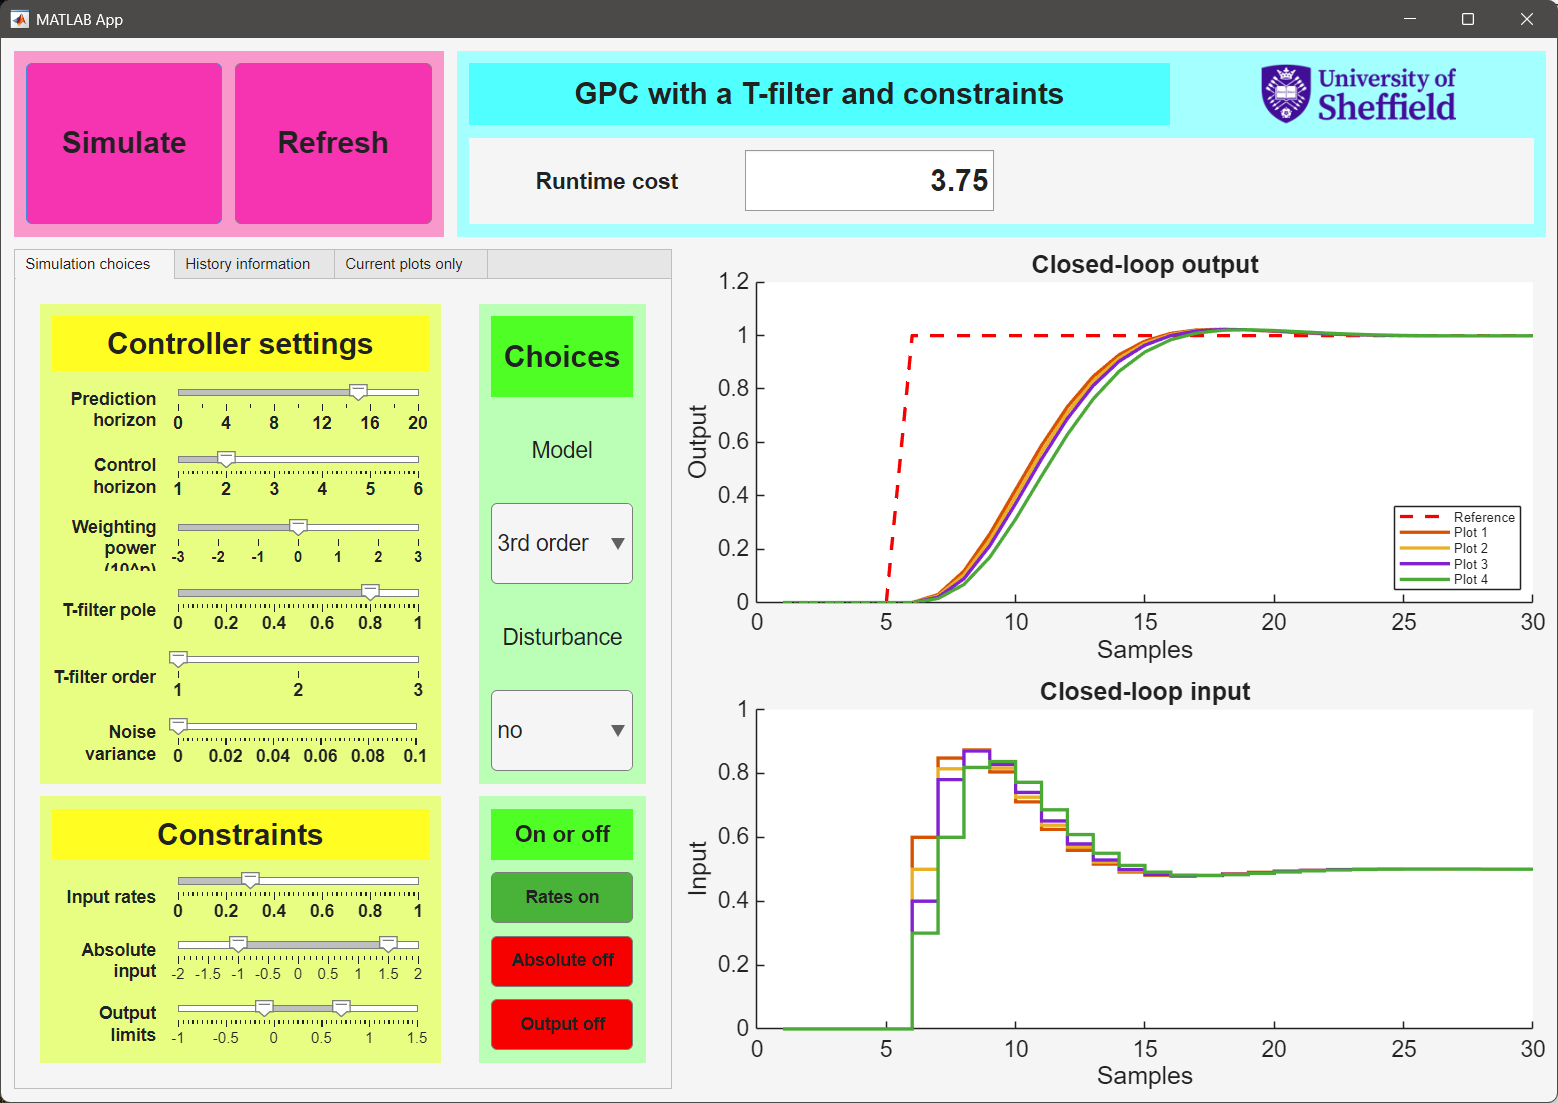

**Figure 4.1** Impact of changing the input rate constraints (all other parameters unchanged)

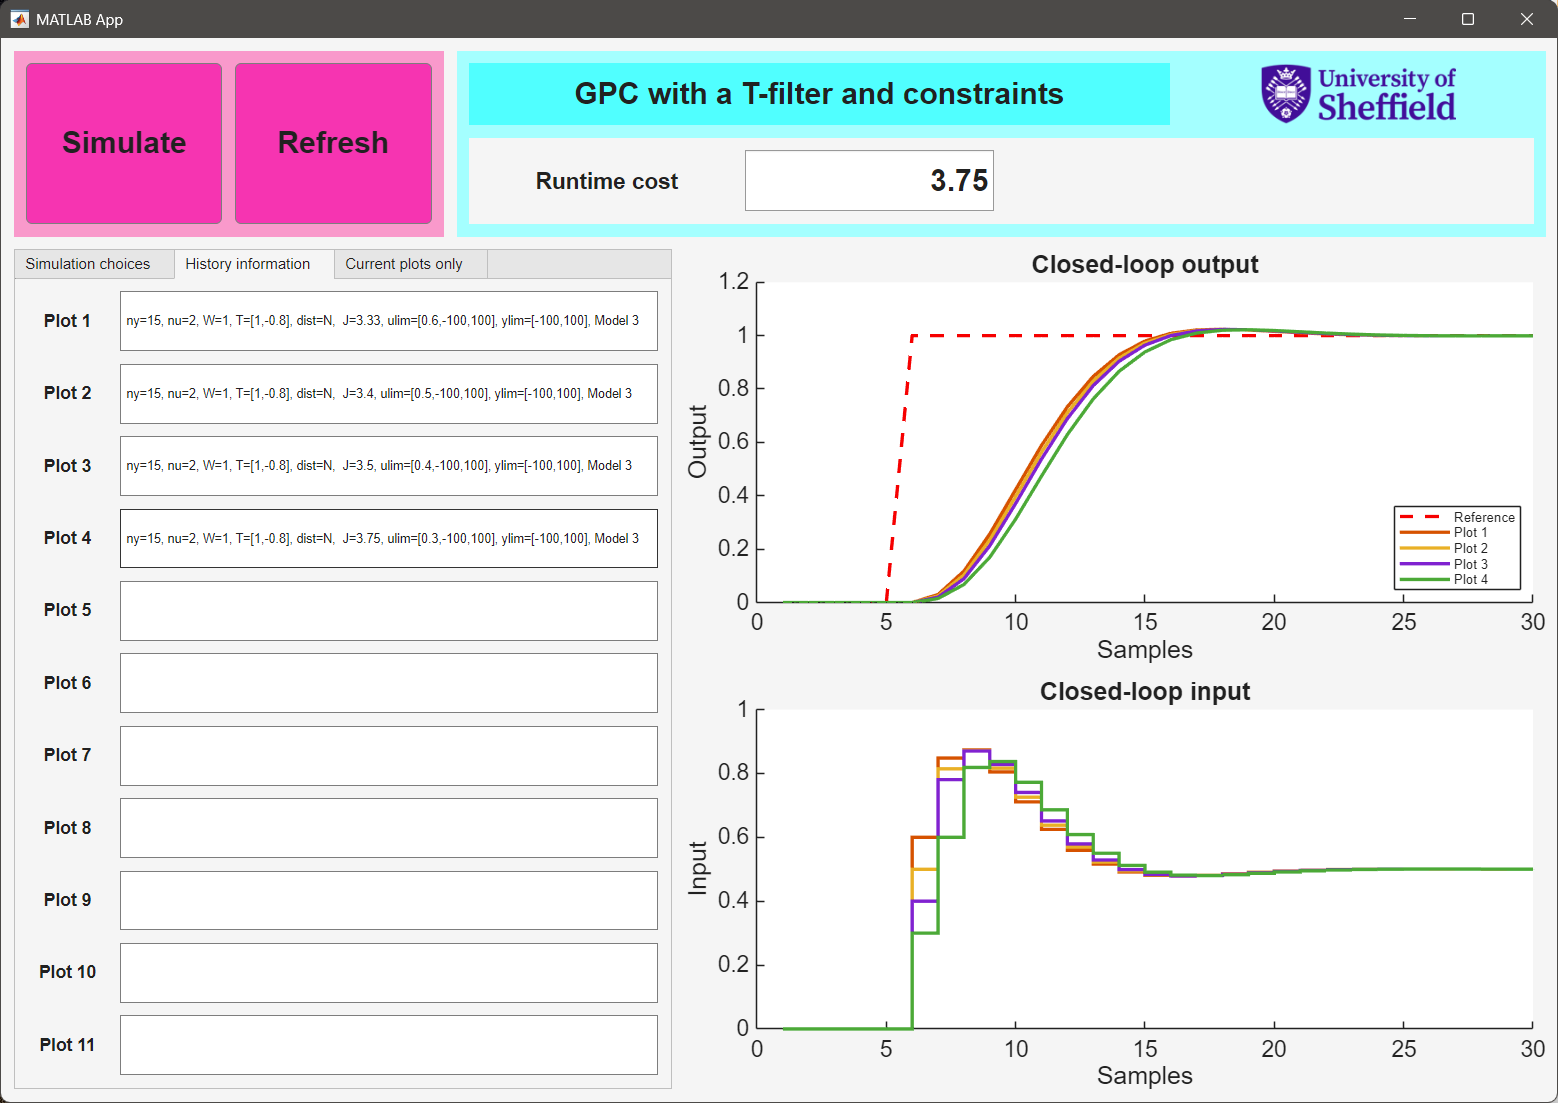

**Figure 4.2** Impact of changing the input rate constraints (all other parameters unchanged)

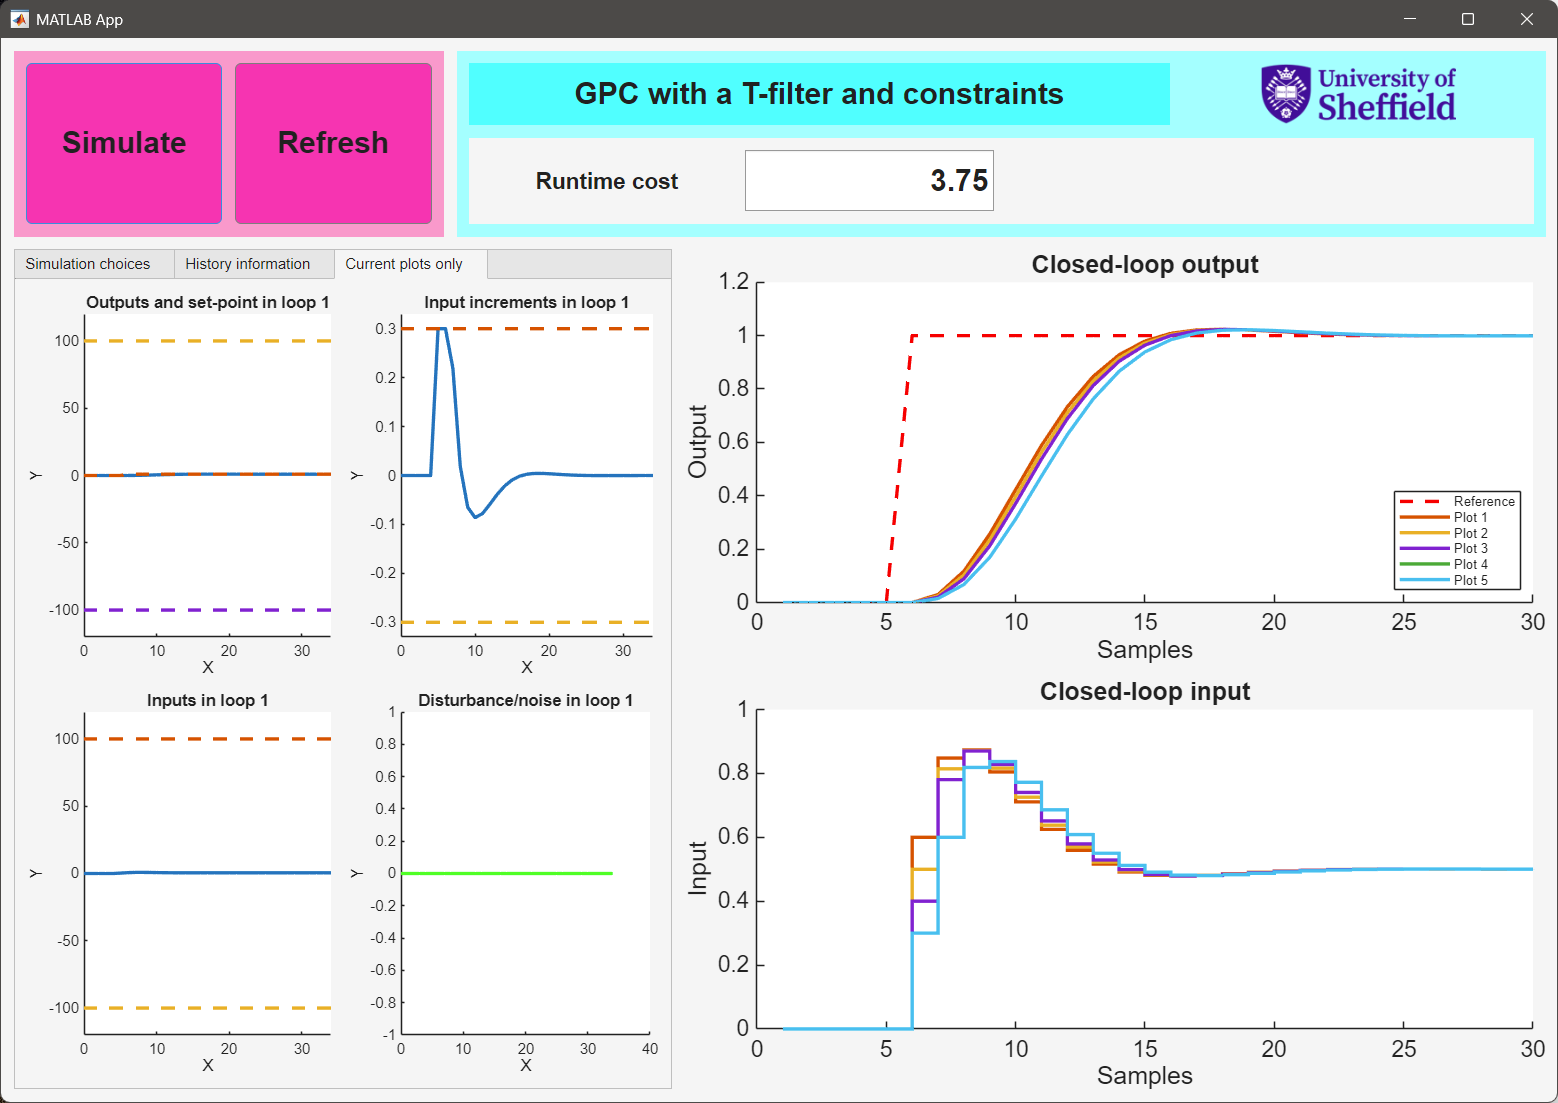

**Figure 4.3** Impact of changing the input rate constraints (all other parameters unchanged)

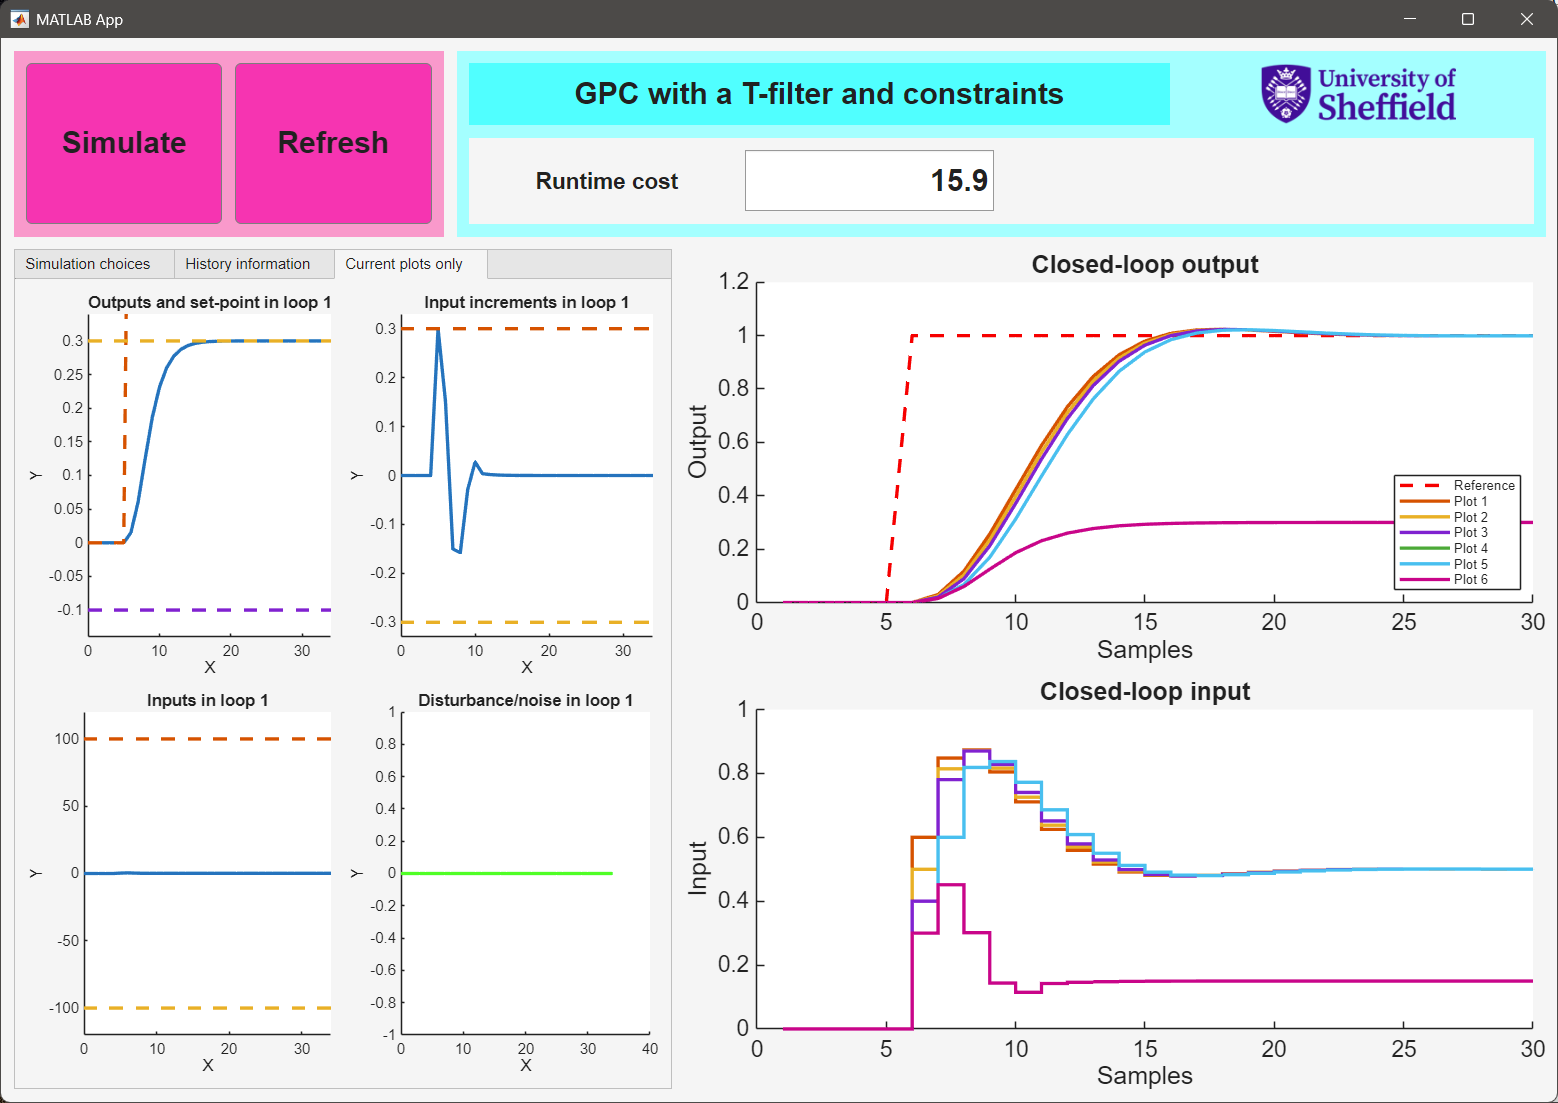

**Figure 4.4** Impact of output constraints - note the target cannot be achieved in this case! 